## Bias/Variance demo

Problem:

Cats can be large or small in length (tail excluded). Larger cats will weight more than smaller cats.

However, above a certain size, cat weight may increase but length will not; the cat will just be fatter.

Variables:

- Input (independent variable): weight in kg

- Output (dependent variable): length in cm

Run this demo multiple times to see different samples from the same population, as well as different random training/test splits.

#### Let's sample a random bunch of cats

num = 25;
[sampleW,sampleL] = randomCatSample(num);
% for plotting:
axislimits =[min(sampleW*.95), max(sampleW*1.05), min(sampleL*.95), max(sampleL*1.05)];


then randomly split it into training and testing subsets

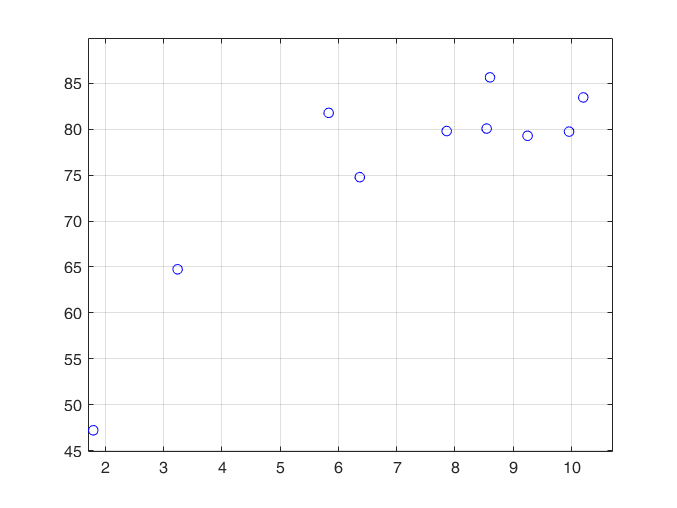

indexes = randperm(num);
splitHere = int64(num*.4); % 40% training, 60% testing
trainingIndexes = indexes(1:splitHere);
testingIndexes = indexes((splitHere+1):end);

% Training set
trainingW = sampleW(trainingIndexes);
trainingL = sampleL(trainingIndexes);
figure(1)
plot(trainingW,trainingL, "ob")
grid
axis(axislimits)

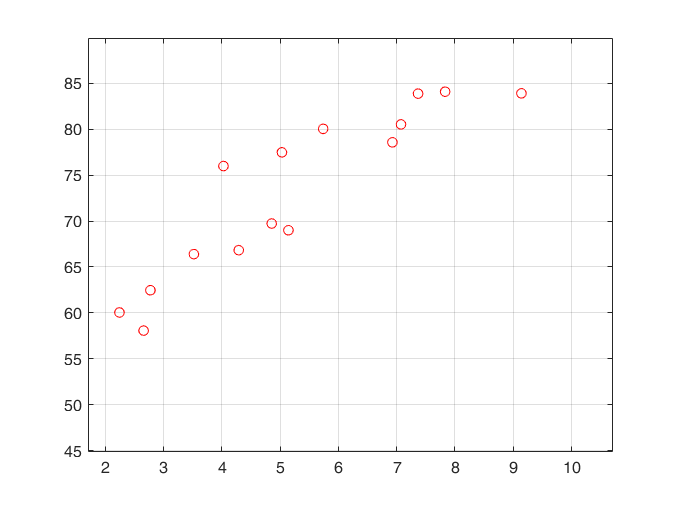


% Testing set
testingW = sampleW(testingIndexes);
testingL = sampleL(testingIndexes);
figure(2)
plot(testingW,testingL, "or")
grid
axis(axislimits)

We solve the problem using two different regression models:

- Linear regression, where we approximate the input-output relationship with the best-fitting linear one

- Nearest-neighbour regression, where a new input point is assigned the same output value as the nearest value in the training set.

In both cases quality is assessed by using MSE.

#### MODEL 1: Linear regression

w = sum((trainingW-mean(trainingW)).*(trainingL-mean(trainingL)))/sum((trainingW-mean(trainingW)).^2);
b = mean(trainingL)-w*mean(trainingW);

Plot model 1 against training set:

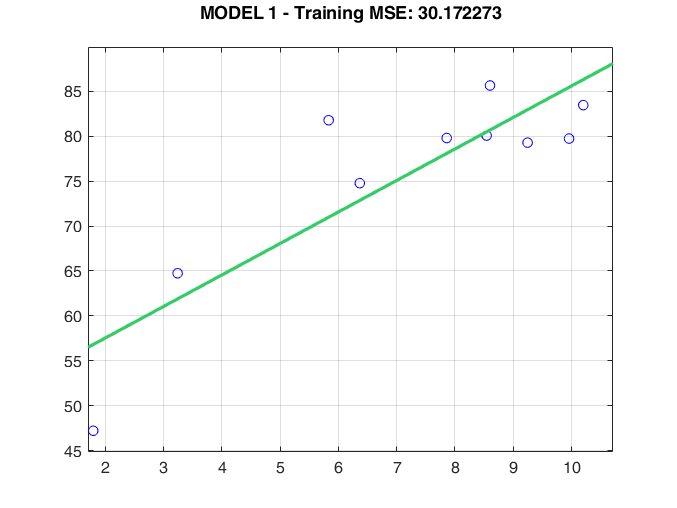

figure(1)
clf
plot(trainingW,trainingL, "ob")
grid
axis(axislimits)
hold on
x = axislimits(1):(axislimits(2)-axislimits(1))/(num*25):axislimits(2);
y = w.*x + b;
plot(x,y,'-','LineWidth',2,'color',[.2,.8,.4])
hold off
% Actually evaluate training MSE
y = w.*trainingW+b;
title(sprintf("MODEL 1 - Training MSE: %f\n", mean((y-trainingL(:)).^2)))

Plot model 1 against testing set:

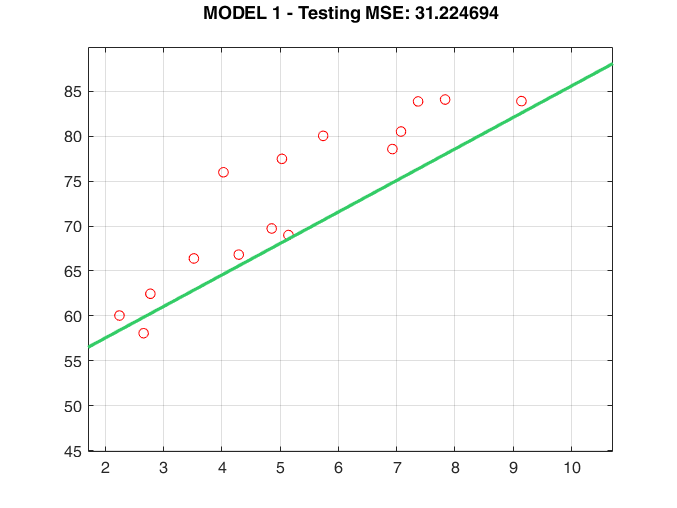

figure(2)
clf
plot(testingW,testingL, "or")
grid
axis(axislimits)
hold on
x = axislimits(1):(axislimits(2)-axislimits(1))/(num*25):axislimits(2);
y = w.*x + b;
plot(x,y,'-','LineWidth',2,'color',[.2,.8,.4])
hold off
% Actually perform test
y = w.*testingW+b;
title(sprintf("MODEL 1 - Testing MSE: %f\n", mean((y-testingL(:)).^2)))

#### MODEL 2: Nearest-neighbour regression

(NN rules need no fitting, everything is done in inference)

Plot model 2 against training set:

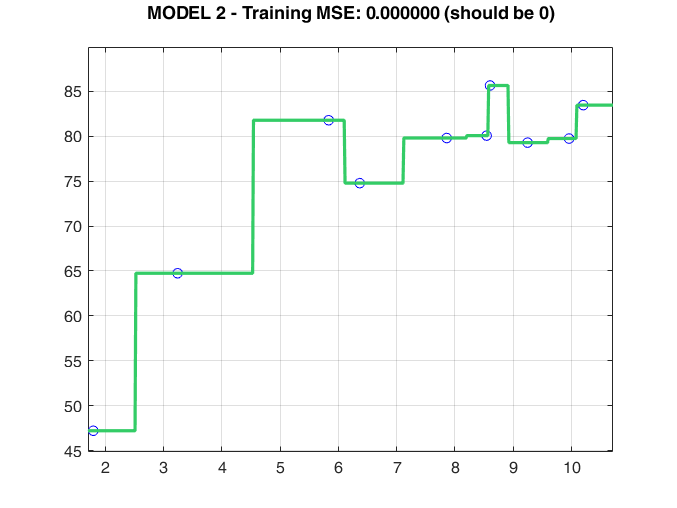

figure(3)
clf
plot(trainingW,trainingL, "ob")
grid
axis(axislimits)
hold on
x = axislimits(1):(axislimits(2)-axislimits(1))/(num*25):axislimits(2);
y = [];
for xval = x
    [~,nearestNeighbour] = min(abs(xval-trainingW));
    y = [y, trainingL(nearestNeighbour)];
end
plot(x,y,'-','LineWidth',2,'color',[.2,.8,.4])
hold off
% Actually evaluate training MSE
y = [];
for xval = trainingW'
    [~,nearestNeighbour] = min(abs(xval-trainingW));
    y = [y; trainingL(nearestNeighbour)];
end
title(sprintf("MODEL 2 - Training MSE: %f (should be 0)\n", mean((y-trainingL(:)).^2)))

Plot model 2 against testing set:

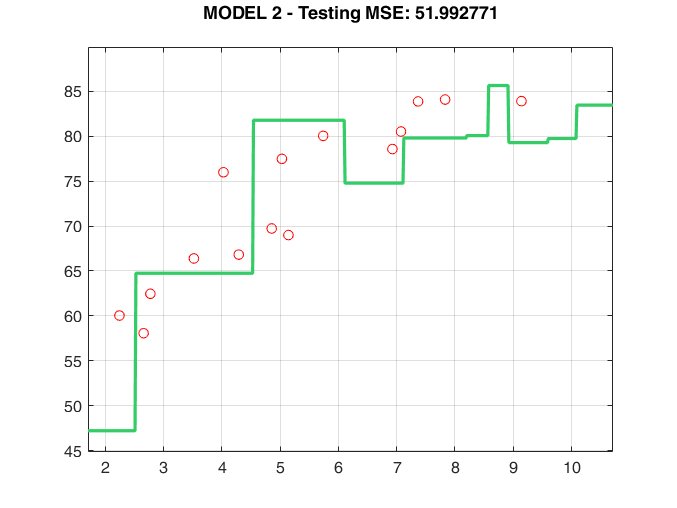

figure(4)
clf
plot(testingW,testingL, "or")
grid
axis(axislimits)
hold on
x = axislimits(1):(axislimits(2)-axislimits(1))/(num*25):axislimits(2);
y = [];
for xval = x
    [~,nearestNeighbour] = min(abs(xval-trainingW));
    y = [y, trainingL(nearestNeighbour)];
end
plot(x,y,'-','LineWidth',2,'color',[.2,.8,.4])
hold off
% Actually perform test
y = [];
for xval = testingW'
    [~,nearestNeighbour] = min(abs(xval-trainingW));
    y = [y, trainingL(nearestNeighbour)];
end
title(sprintf("MODEL 2 - Testing MSE: %f\n", mean((y(:)-testingL(:)).^2)))

### Functions

This is the "true" law that relates weight to length. Of course it contains some randomness:

function length = catLength(weight)
  g_in = .5;
  g_out = 120;
  b_0 = .3;
  length = g_out*(1./(1+exp(-g_in*weight))-b_0);
  length = normrnd(length, 3);
end

This is the samping function that returns a random sample of size num 

function [weight, length] = randomCatSample(num)
  minWeight = 2;
  maxWeight = 10;
  stepSize = (maxWeight-minWeight)/(num-1);
  weight = normrnd(minWeight:stepSize:maxWeight,stepSize/2);
  while any(weight<1) % unreasonable values, retry
    weight = normrnd(minWeight:stepSize:maxWeight,stepSize/2);
  end
  weight = weight(:); % make sure it is a column vector
  length = catLength(weight);
end